**Script to demonstrate a FjordRPM simulation of fjord response to**

RACMO 2024 subglacial discharge input from Store Glacier. The shelf conditions are constant in time but vary with depth, using input data from Uummannaq Bay. We use a 80 km long fjord, 6 km wide, with no sill. There are icebergs. The main example here assumes a single glacier with a single plume.

%% clear workspace and close any figures to ensure clean environment
clear; close all;


% put FjordRPM code on path - need to update to the location of your code
path2sourcecode = 'C:\Users\efc4\Documents\MATLAB\fjordrpm\';
addpath(genpath(path2sourcecode));



%% get basic constants and default controlling parameters
p = default_parameters;

% can adjust any of the default parameters afterwards if needed
% p.C0 = 5e4; % for example adjust shelf exchange parameter
% p.run_plume_every = 10; % or update plume model only every 10 time steps

% load subglacial discharge from Mankoff (2020)
sgFile = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\processed\Store_Qsg_2024.mat";
Ssg = load(sgFile);
fsg = Ssg.f;


%% set up fjord geometry
p.W = 6e3; % fjord width (m)
p.L = 80e3; % fjord length (m)
p.H = 800; % fjord depth (m)
p.sill = 0; % p.sill=1 for presence of sill, p.sill=0 for no sill
%p.Hsill = 400; % sill depth below surface (m), only used if p.sill=1


%% set up glacier geometry
% (only used if there is non-zero subglacial discharge)
p.Hgl = 800; % grounding line depth (m)
p.Wp = 250; % subglacial discharge plume width (m)

% in the case of multiple plumes, either at the same glacier or at
% different glaciers, specify vectors of grounding line depth and plume
% width. for example, 3 glaciers of grounding line depth 800, 700, 600 m
% and plume width 300, 200 and 300 m would require
% p.Hgl = [800,700,600];
% p.Wp = [300,200,300];


%% set up model layers
p.N = 40; % number of layers
a.H0 = (p.H/p.N)*ones(p.N,1); % layer thicknesses, here taken to be equal


%% set up time stepping from subglacial discharge dataset

dt = 0.2;
t_end = max(fsg.tsg);
t = fsg.tsg(1):dt:fsg.tsg(end);
p.t_save = fsg.tsg;


## set up shelf forcing


%% Load CTD shelf forcing

glorysFile = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\processed\GLORYS12\fjordrpm_shelf_forcing.mat";

Sgl = load(glorysFile,'f');

fsh = Sgl.f;

whos fsh

  Name      Size              Bytes  Class     Attributes

  fsh       1x1             8082212  struct              



size(fsh.Ts)

ans =           41       12171


size(fsh.Ss)

ans =           41       12171


size(fsh.zs)

ans =     41     1


size(fsh.ts)

ans =            1       12171



fsh = Sgl.f;

disp(length(fsh.ts))

       12171



disp(length(fsg.tsg))

   366



%%
nt = length(fsg.tsg);

fsh.Ts = fsh.Ts(:,1:nt);
fsh.Ss = fsh.Ss(:,1:nt);
fsh.ts = fsh.ts(1:nt);

%% ensure correct orientation
fsh.zs = -abs(fsh.zs(:));

%% Combine forcings into final structure

f = struct;

% Shelf forcing
f.ts = fsg.tsg;   % 1:366 model time axis to align with discharge time
f.zs = fsh.zs;
f.Ss = fsh.Ss;
f.Ts = fsh.Ts;

% Subglacial forcing
f.tsg = fsg.tsg;
f.Qsg = fsg.Qsg;

disp(max(abs(diff(f.Ts(10,:)))))

    0.5479




%% fjord initial conditions
% set up to be same as initial shelf profiles
[a.T0, a.S0] = bin_shelf_profiles(f.Ts(:,1), f.Ss(:,1), f.zs, a.H0);



%% fjord initial conditions
% set up to be same as initial shelf profiles
[a.T0, a.S0] = bin_shelf_profiles(f.Ts(:,1), f.Ss(:,1), f.zs, a.H0);



% set up icebergs
% need to specify the iceberg-ocean surface area in each layer. assume an 
% exponential profile with total surface area 200 km^2 = 2e8 m^2
zc = cumsum(a.H0)-a.H0/2; % depth of centre of layers
iceprofile = exp(-zc/100); % profile before scaling
a.I0 = (1e8/sum(iceprofile))*iceprofile; % surface area profile used by FjordRPM (m^2)


%% run the model
% p.plot_runtime = 1; % plot while simulation runs - fun but quite slow
s = run_model(p, t, f, a);

Riverine input flux (f.Qr) not specified: setting to 0.
Temperature of riverine input (f.Tr) not specified: setting to 0.
Salinity of riverine input (f.Sr) not specified: setting to 0.
Air temp (f.Ta) not specified: setting air-sea heat flux to 0.


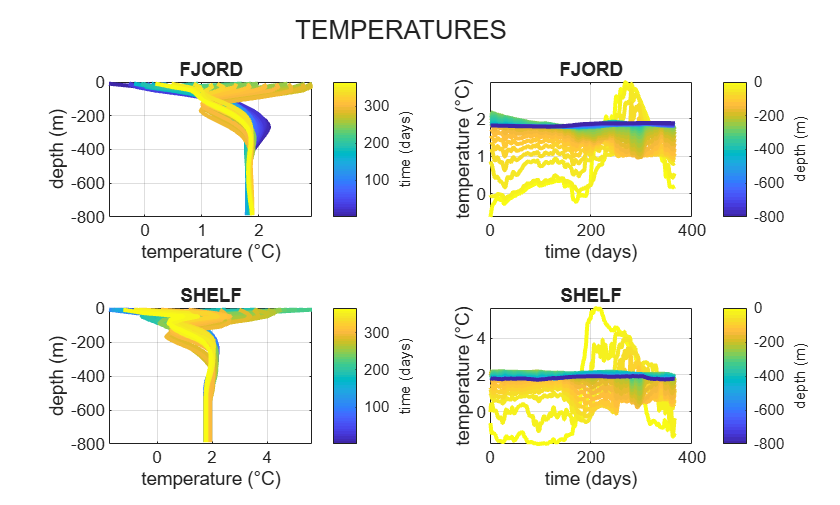

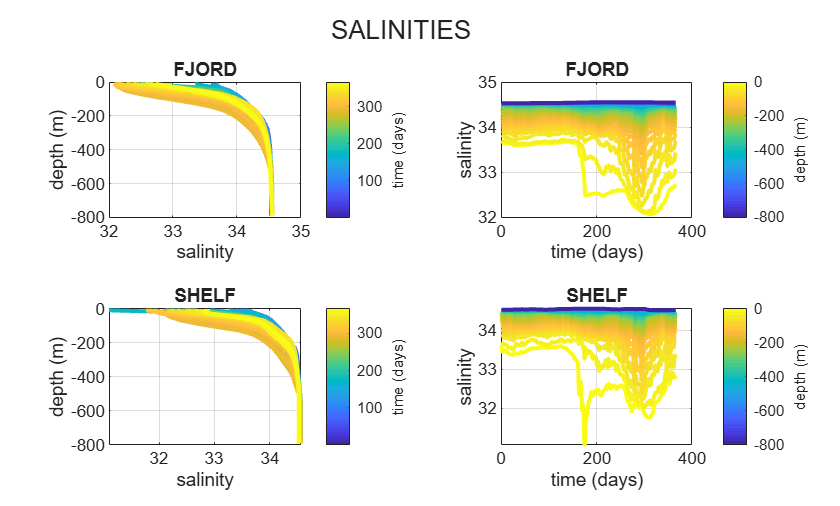

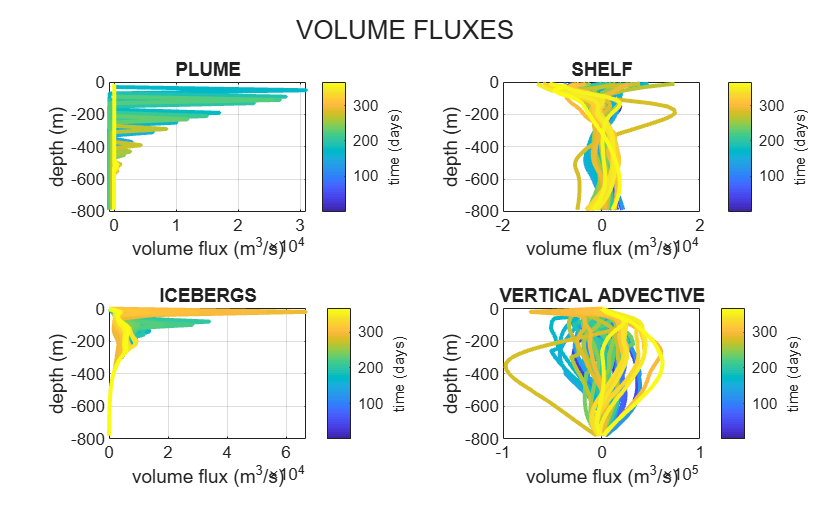

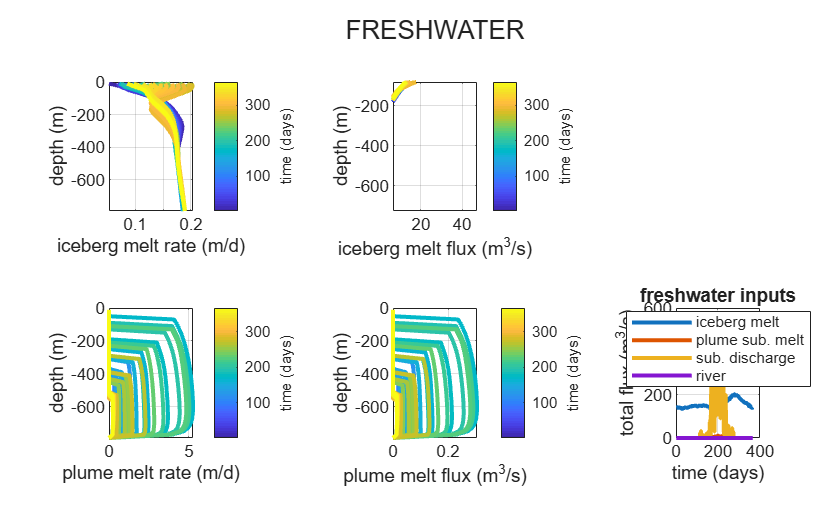


%% save the output
save experiment5_mankoff_subglacial_discharge.mat s p t f a

%% make an animation of the output (takes a few minutes)
% animate(p,s,50,'example1_subglacial_discharge');

%% make basic plots of the output
plotrpm(p,s,50);